# **P02: Señales Continuas**

**Integrantes:**

Contreras Avilés Citlali Anahí

Gallegos Ruiz Diana Abigail

Morgado Reséndiz Lisardo René

Ramírez Aniceto Lauro Alexis

Rojas Gómez Ian

**PROFESOR:** Rafael Martínez Martínez

**GRUPO:** 2TV1

## **Introducción**

**Una señal se define como la manifestación de información y esta se puede analizar de diferentes formas, en esta práctica se mostrará el manejo de MatLab para poder representar Señales Continuas a través del tiempo.**

**Se adjunta la imagen del resultado del Problema 4 de esta práctica, el código se realizó sobre Python en la plataforma de COLAB y se adjunta también el archivo de este **[código](https://colab.research.google.com/drive/1Ipc0keZYIFvrVrrOFOjWefKxuQQcnz0x?usp=sharing).

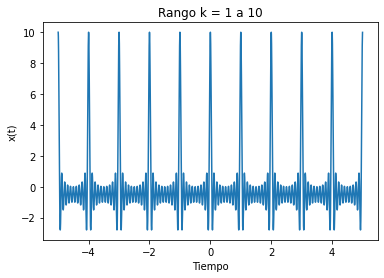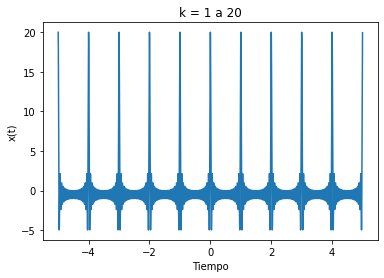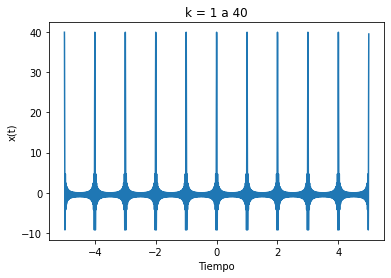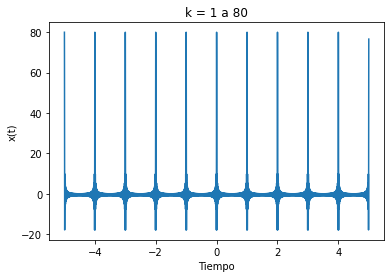

## 1-Reproducir la sección 1.11 del libro de Lathi (Versión de clase).

### 1.11 MATLAB: Trabajando con funciones.

Trabajar con funciones es fundamental para las aplicaciones de señales y sistemas. MATLAB proporciona métodos de definición y evaluación de funciones. Por lo tanto, la comprensión y el uso competente de estos métodos es necesario y beneficioso.

#### 1.11-1 Funciones anónimas.

Muchas funciones simples es más conveniente representarlas usando funciones anónimas de MATLAB. Una función anónima te provee una representación simbólica de una función definida en términos de los operadores de MATLAB, funciones u otras funciones anónimas. Por ejemplo, considera definiendo la siguiente función:

                                                                        
$$f\left(t\right)=e^{-t} \cos \left(2\pi t\right)$$


f = @(t) exp(-t).*cos(2*pi*t);

En este contexto, el símbolo @ identifica la expresión como una función anónima, a la cuál se le asigna el nombre de f. Los paréntesis después del signo @ son usados para identificar la variable independiente de la función, la cuál en este caso es la variable de tiempo t. Los argumentos ingresados como t son locales a la función anónima y no están relacionadas a ninguna de las variables del área de trabajo con los mismos nombres.

    Una vez definida, $f\left(t\right)\;$puede ser evaluada simplemente pasando los argumentos de entrada de su interés, por ejemplo:

t = 0;
f(t)

ans = 1

   Evalúa $f\left(t\right)$en $t=0$, confirmando el resultado esperado de la unidad, el mismo resultado se obtiene si pasamos $t=0$ directamente.

f(0)

ans = 1

    Si ingresamos un vector podrémos hacer evaluación de múltiples valores simultaneamente. Considera la tarea de graficar $f\left(t\right)$sobre el intervalo $\left(-2\le t\le 2\right)$. $f\left(t\right)$ debería oscilar cuatro veces con una envolvente decadente. Desde que la precisión de los bosquejos a mano no es tan buena, las gráficas generadas de MATLAB son una alternativa atractiva. Cómo en los siguientes ejemplos ilustrados, se debe tener cuidado para asegurar que el resultado sea de confianza.

    Suponga que el vector t es escogido para incluir únicamente los enteros contenidos en $\left(-2\le t\le 2\right)$, es decir, $\left\lbrack -2,-1,0,1,2\right\rbrack$.

t = (-2:2);

    El vector de entrada es evaluado para formar un vector de salida.

f(t)

ans =     7.3891    2.7183    1.0000    0.3679    0.1353


El comando plot grafica el resultado, el cuál se muestra en la Figura 1.46

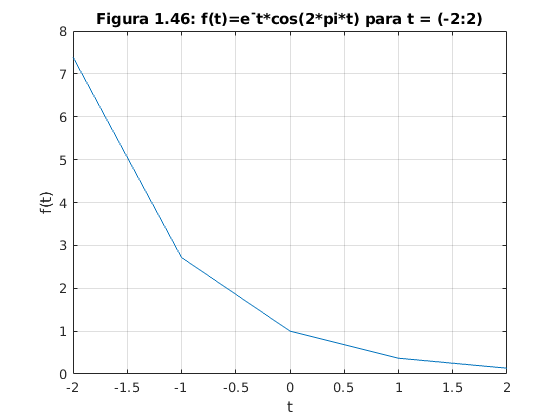

plot(t,f(t));
title('Figura 1.46: f(t)=e^-t*cos(2*pi*t) para t = (-2:2)');
xlabel('t'); ylabel('f(t)'); grid;

Las líneas de rejilla , añadidas usando el comando grid, ayudan con la identificación, desafortunadamente, la gráfica no muestra el comportamiento de oscilación esperado, por lo que se requieren más puntos para representar adecuadamente $f\left(t\right)$

    La pregunta, entonces, es ¿Cuántos puntos son suficientes? Si se seleccionan muy pocos, se pierde la información, si son muchos se desperdicia memoria y tiempo, es necesario balancearlos. Para funciones oscilatorias, graficar de 20 a 200 puntos por oscilación es normalmente adecuado. Para este caso,t es elegido para dar 100 puntos por oscilación.

t = (-2:0.01:2);

De nuevo, la función es evaluada y graficada.

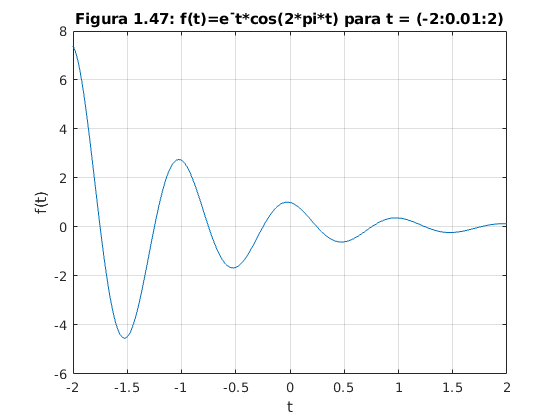

plot(t,f(t));
title('Figura 1.47: f(t)=e^-t*cos(2*pi*t) para t = (-2:0.01:2)');
xlabel('t'); ylabel('f(t)'); grid;

El resultado, mostrado en la Figura 1.47, es una representación adecuada de f(t).

#### 1.11-2 Operadores relacionados y la función escalón unitario.

La función escalón unitario $u\left(t\right)$surge naturalmente en muchas situaciones prácticas. Por ejemplo, una función escalón puede modelar el acto de encendido de un sistema. Con la ayuda de operadores relacionales, las funciones anónimas pueden representar la función escalón unitario.

    En MATLAB, un operador relacional comprara dos obejots, si la comparación es verdadera, regresa un true lógico (1), si la comparación es falsa, regresa 0. Algunas veces llamadas funciones indicadores, los operadores relacionales indican cuando alguna condición es verdadera. Tenemos 6 operadores relacionales disponibles: $<,>,\le ,\ge ,==,y~=$.

    La función escalón unitario es fácilmente definida usando el operador relacional >=:

u = @(t) 1.0.*(t>=0);

Cualquier función con un salto de discontinuidad, cómo el escalón unitario, son difíciles de graficar, considera graficar u(t) usando t = (-2:2).

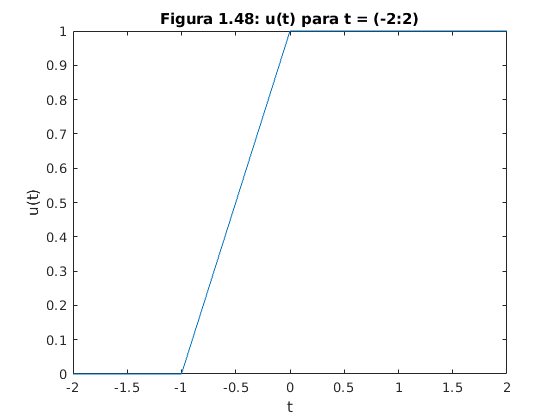

t = (-2:2); plot(t,u(t));
title('Figura 1.48: u(t) para t = (-2:2)');
xlabel('t'); ylabel('u(t)');

Dos problemas significantes aparecen en la gráfica resultante, mostrada en la Figura 1.48. Primero, MATLAB automáticamente escala el trazado de ejes para unir la información herméticamente. En este caso, esta característica deseable oscurece la mayoría de la gráfica. Segundo, MATLAB conecta los datos graficados con líneas haciendo que un salto a 'verdadero' sea difícil de ver. 

    El primer problema es corregido agrandando verticalmente la caja delimitadora con el comando axis, el segundo problema se reduce, mas no se elimina, añadiendo puntos al vector t.

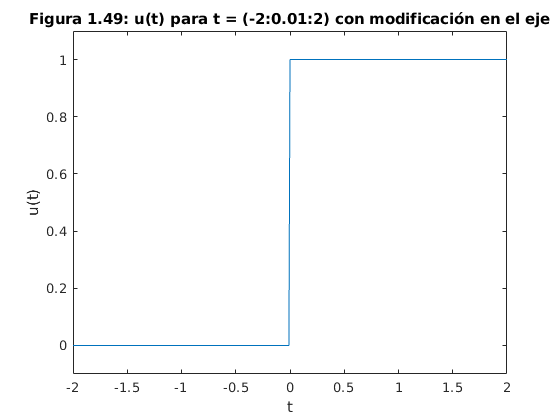

t = (-2:0.01:2); plot(t,u(t));
title('Figura 1.49: u(t) para t = (-2:0.01:2) con modificación en el eje');
xlabel('t'); ylabel('u(t)');
axis([-2 2 -0.1 1.1]);

El vector de cuatro argumentos de 'axis' especifica eje x mínimo,  eje x máximo, eje y mínimo, eje y máximo, respectivamente. Los resultados dados se muestran el la Figura 1.49.

    Los operadores relacionales pueden ser combinados usando los operadores lógicos AND, OR, &, |, y ~, respectivamente. Por ejemplo, (t>0)&(t<1) and ~((t<=0) | (t>=1)) ambos prueban si 0<t<1.

Para demostrarlo, considera definiendo y graficando el pulso unitario p(t)=u(t)-u(t-1), como se muestra en la Figura 1.50:

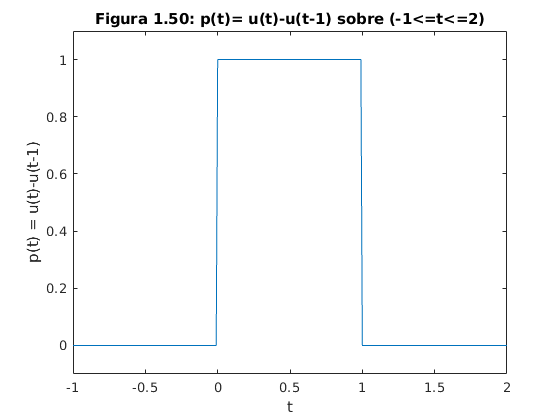

p = @(t) 1.0.*((t>=0)&(t<1));
t = (-1:0.01:2); plot(t,p(t));
title('Figura 1.50: p(t)= u(t)-u(t-1) sobre (-1<=t<=2)');
xlabel('t'); ylabel('p(t) = u(t)-u(t-1)');
axis([-1 2 -.1 1.1]);

Como las funciones anónimas pueden ser construidas usando otras funciones anónimas, pudimos usar nuestra función escalón unitario para definir p(t) como p = @(t) u(t)-u(t-1).

    Para operadores escalares, MATLAB también soporta dos constructores de circuitos lógicos cortos. Un circuito lógico corto AND es realizado usando &&, y un circuito lógico corto OR es realizado usando | |. Estos a menudo son más eficientes que los operadores lógicos tradicionales porque ellos prueban  la segunda porción de la expresión sólo cuando es necesario. Es decir, Cuando la expresión A es falsa en (A&&B), la expresión escalar B no es evaluada ya que un resultado falso es seguro. De manera similar, la expresión B no es evaluada cuando la expresión A es verdadera en (A || B), porque un resultado verdadero ya es seguro.

#### 1.11-3 Visualizando operaciones en la variable independiente.

Comúnmente se encuentran dos operaciones en la variable independiente de una función: shifting y scaling. Las funciones anónimas son buen ejemplo para investigar ambas operaciones.

    Considere $g(t) = f(t)u(t) = e^{-t}cos(2\pi t)u(t)$, una versión causal de f(t). MATLAB fácilmente multiplica funciones anónimas. Así, creamos g(t) multiplicand nuestras funciones anónimas f(t) y u(t):

g = @(t) f(t).*u(t);

 Una operación combinado de shifting y scaling es representado por $g\left(\textrm{at}+b\right)$, dón de a y b son constantes reales arbitrarias. Como un ejemplo, considere graficar $g\left(2t+1\right)$ sobre $\left(-2\le t\le 2\right)$. Con a = 2, la función se comprime con un factor de 2, resultado en el doble de oscilaciones por unidad  de t. Añadiendo la condición b > 0, transforma la forma de la onda a la izquierda. Dada la función anónima g, una gráfica acertada es cercanamente trivial de obtener.

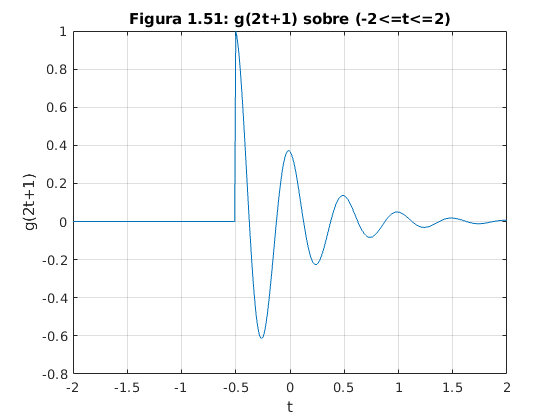

t = (-2:0.01:2);
plot(t,g(2*t+1)); xlabel('t'); ylabel('g(2t+1)'); grid;
title('Figura 1.51: g(2t+1) sobre (-2<=t<=2)');

La Figura 1.51 confirma la compresión en la forma de onda y la transformación izquierda. Como último punto, comprueba que la función g(.) se enciende cuando el argumento ingresado es cero, para eso, g(2t+1) debería encenderse cuando 2t + 1 = 0 o cuando t = -0.5, un hecho confirmado de nuevo en la Figura 1.51.

    Después, considere graficar g(-t+1) sobre (-2<= t <= 2). Como a < 0, la forma de la onda será reflejada, Añadiendo la condición b>0 transforma la forma de onda final a la derecha.

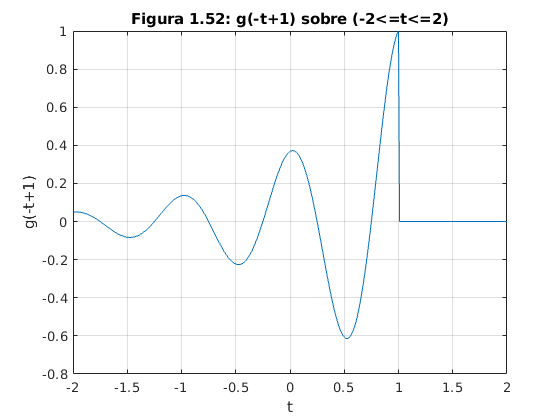

plot(t,g(-t+1)); xlabel('t'); ylabel('g(-t+1)'); grid;
title('Figura 1.52: g(-t+1) sobre (-2<=t<=2)');

La Figura 1.52 confirma ambos.

    Para este punto, las figuras 1.51 y 1.52 podrían haber sido bosquejadas racionalmente a mano, considere graficar la función más complicada $h\left(t\right)=g\left(2t+1\right)+g\left(-t+1\right)\;\textrm{sobre}\left(-2\le t\le 2\right)\;\;$(Figura 1.53); Un bosquejo a mano sería un poco difícil. Con MATLAB, el trabajo es mucho menos pesado.

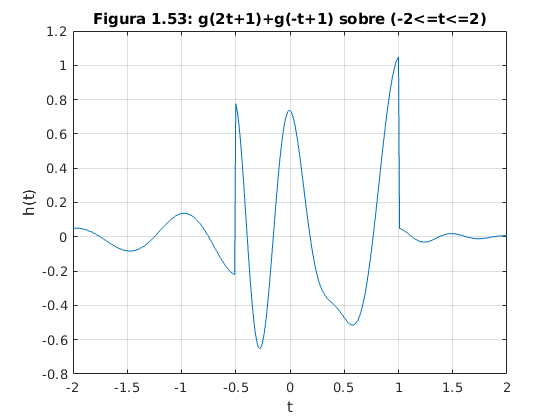

plot(t,g(2*t+1)+g(-t+1)); xlabel('t'); ylabel('h(t)'); grid;
title('Figura 1.53: g(2t+1)+g(-t+1) sobre (-2<=t<=2)');

#### 1.11-4 Integración numérica y estimación de la energía de la señal.

Las señales interesantes a menudo tienen expresiones matemáticas no triviales. Calcular la energía de las señales, el cuál involucra integrar el cuadrado de estas expresiones puede ser una tarea difícil. Afortunadamente, muchas integrales difíciles pueden ser estimadas correctamente por muchas técnicas de integración numérica.

Incluso si la integral parece simple, la integración numérica provee una buena manera de verificar resultados analíticos.

    Para empezar, considere la señal simple $x\left(t\right)=e^{-t} \left(u\left(t\right)-u\left(t-1\right)\right)$. La energía de x(t) es expresada como $E_x =\int_{-\infty }^{\infty } {\left|x\left(t\right)\right|}^2 \;\textrm{dt}=\int_0^1 e^{-2t} \textrm{dt}$. Integrando $E_x$=0.5(1-$e^{-2}$)  $\approx$ 0.4323. La integral de energía puede ser evaluada numericamente también. La Figura 1.27 ayuda a ilustrar el método simple de aproximación rectangular: evalúa la integral en los puntos uniformemente separada por $\Delta t$, multiplica cada uno por $\Delta t$ para calcular las áreas rectangulares y después sumar todos los rectángulos. Primero, creamos la función x(t).

x = @(t) exp(-t).*((t>=0)&(t<1));

Con $\Delta t$= 0.01, un vector de tiempo es creado.

t = (0:0.01:1);

El resultado final es calculado utilizando el comando sum:

E_x = sum(x(t).*x(t)*0.01)

E_x = 0.4367

El resultado no es perfecto, pero a un 1% de error relativo es cercano. Reduciendo $\Delta t$, la aproximación es mejorada. Por ejemplo, $\Delta t$= 0.001 da E_x = 0.4328, o 0.1% de error relativo.

    Aunque es simple de visualizar, la aproximación rectangular no es la mejor técnica de integración numérica. La función de MATLAB quad implementa una mejor integración numérica llamada la cuadratura adaptativa recursiva de Simpson. Para funcionar, quad requiere una función para describir la integral, el límite inferior de la integración y el límite superior. Note que no hay necesidad de especificar $\Delta t$.

    Para usar quad para estimar $E_x$, la integral necesita ser descrita:

x_squared = @(t) x(t).*x(t);

Estimando $E_x$ inmediatamente nos da:

E_x = quad(x_squared,0,1)

E_x = 0.4323

En este caso, el error relativo es -0.0026%

    Las mismas técnicas pueden ser usadas para estimar la energía de señales más complejas. Considere g(t), definida previamente. La energía es expresada como $E_g =\int_0^{\infty } e^{-2t} \cos \left(2\pi t\right)\textrm{dt}$. Una solución más cercana existe, pero toma algo de esfuerzo. MATLAB provee una respuesta más rápido.

g_squared = @(t) g(t).*g(t);

Aunque el límite superior de integración es infinito, la envolvente exponencial decadente g(t) es efectivamente cero antes de t = 100. Para esto, un límite superior de t = 100 es usada junto con $\Delta t$ = 0.001.

t = (0:0.001:100);
E_g = quad(g_squared,0,100)

E_g = 0.2562

Una aproximación ligeramente mejor es obtenida con la función quad:

E_g = quad(g_squared,0,100)

E_g = 0.2562

## **Problema 2: Problema 1.2-2 Lathi**

clear all; close all; clc;


**Señal x(t) ilustrada de la Fig. P1.2-2**

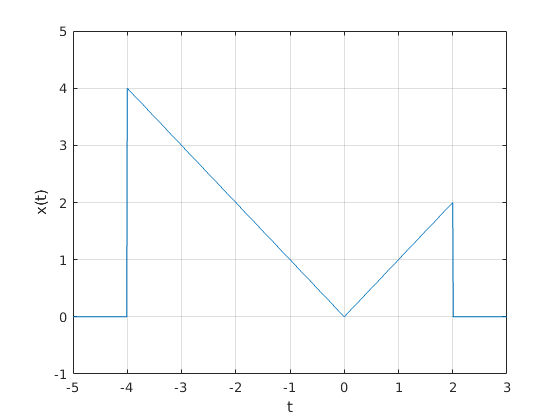

t = (-5: 0.01: 3);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(t));
xlabel('t');
ylabel('x(t)');
axis([-5 3 -1 5]);
grid;

**a) x(t-4)**

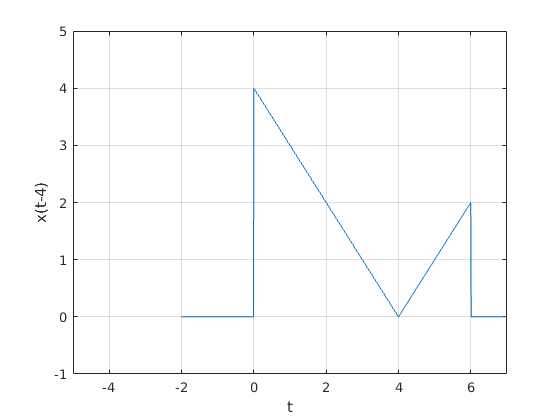

t = (-2: 0.01: 7);
f = @(t) abs(t-4).*((t>=0)&(t<=6));

plot(t, f(t));
xlabel('t');
ylabel('x(t-4)');
axis([-5 7 -1 5]);
grid;

**b) x(t/1.5)**

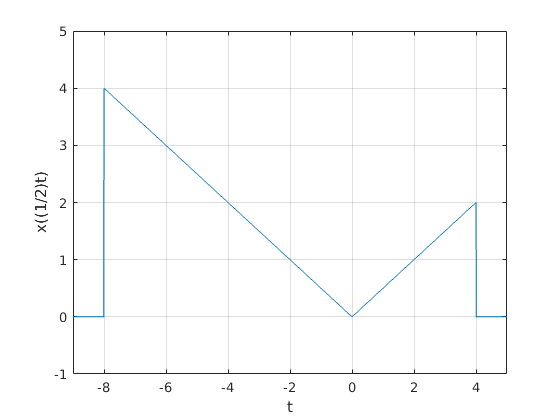

t = (-9: 0.01: 5);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(0.5*t));
xlabel('t');
ylabel('x((1/2)t)');
axis([-9 5 -1 5]);
grid;

**c) x(-t)**

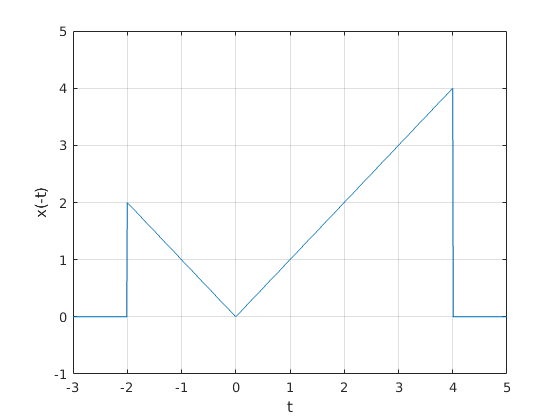

t = (-3: 0.01: 5);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(-t));
xlabel('t');
ylabel('x(-t)');
axis([-3 5 -1 5]);
grid;

**d) x(2t-4)**

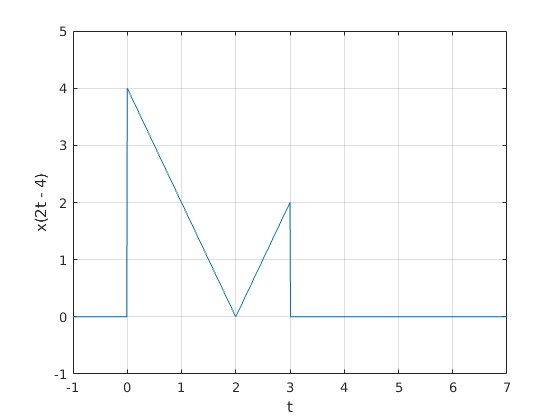

t = (-2: 0.01: 7);
f = @(t) abs(2*t - 4).*((t>=0)&(t<=3));

plot(t, f(t));
xlabel('t');
ylabel('x(2t - 4)');
axis([-1 7 -1 5]);
grid;

**e) x(2-t)**

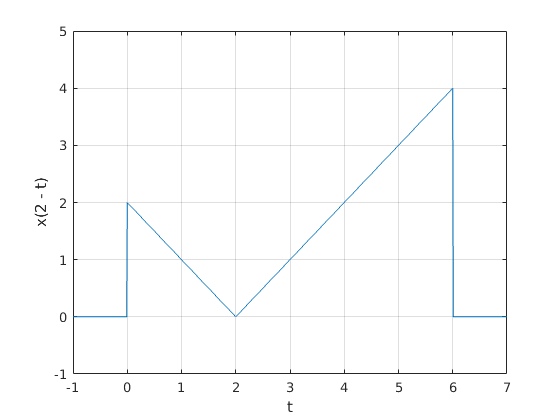

t = (-1: 0.01: 7);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(2-t));
xlabel('t');
ylabel('x(2 - t)');
axis([-1 7 -1 5]);
grid;

## **Problema 3: Problema 1.11-1 Lathi**

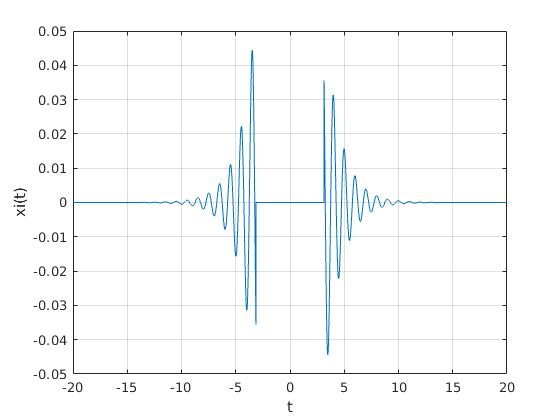

clear all; clc; close all;

u = @(t) 1.0*(t>=0);
x = @(t) 2.^(-t).*cos(2 * pi * t).*u(t-pi);

xi = @(t) (x(t) - x(-t))/2;

t = [-20: 0.001: 20];

plot(t, xi(t));
xlabel('t');
ylabel('xi(t)');
grid;

## **Problema 4: Construir la gráfica de **$x(t)=\sum_{k=1}^{10}\cos(2\pi kt)$

clear all; close all; clc;
syms t

**Rango k = 1 a 10**

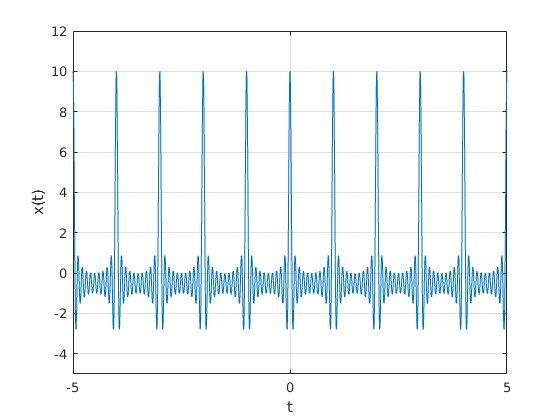

sf = 0;
for k = 1:10
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -5 12]);
grid;

**Rango k = 1 a 20**

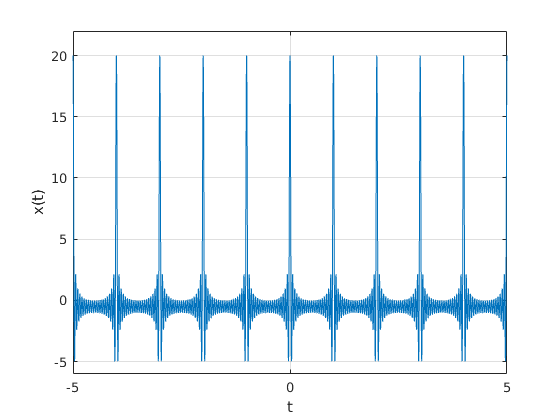

sf = 0;
for k = 1:20
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -6 22]);
grid;

**Rango k = 1 a 40**

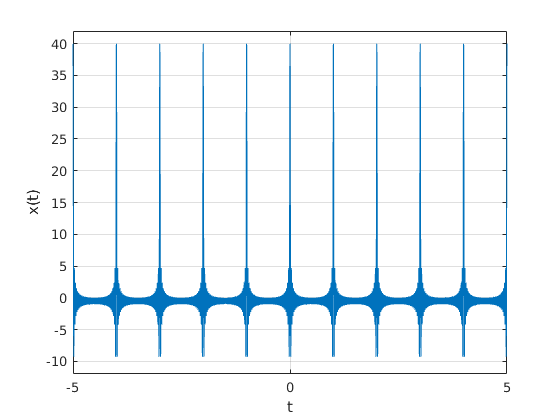

sf = 0;
for k = 1:40
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -12 42]);
grid;

**Rango k = 1 a 80**

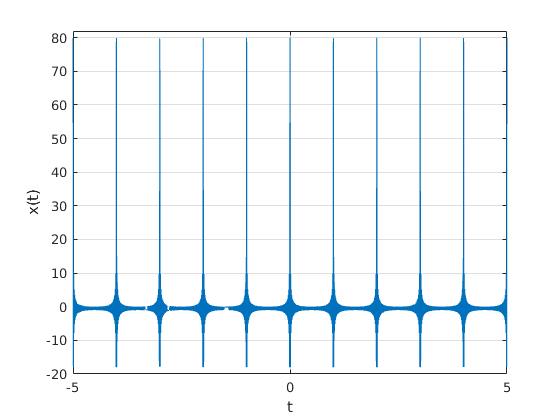

sf = 0;
for k = 1:80
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -20 82]);
grid;

## Problema 5: Problema 1.11-3 Lathi

clear all; clc; close all;


**a) Graficar Re{x(t)} contra Im{x(at)} para a = 0.5, 1 y 2 en el intervalo **$-10\le t\le 10$

t = [ -10: 0.001: 10];
u = @(t) 1.0.*(t>=0);
x = @(t) exp(t*(1+j*2*pi)).*u(-t);
y = @(t) real(2*x((-5-t)/2));

Para a = 0.5

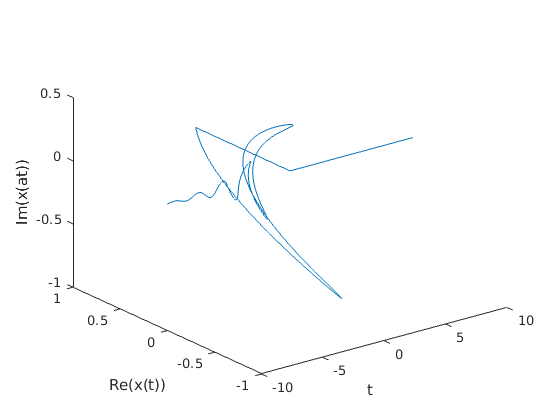

a = 0.5;

plot3(t, real(x(t)), imag(x(a*t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(at))');

Para a = 1

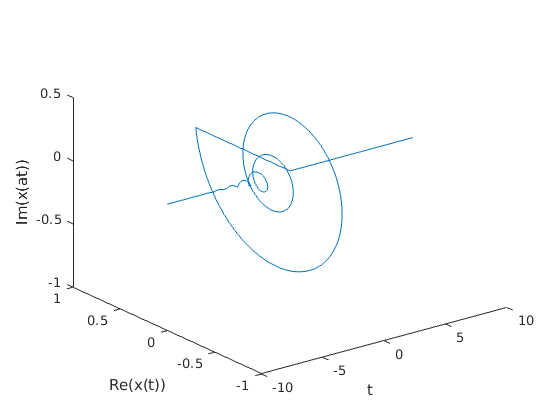

a = 1;

plot3(t, real(x(t)), imag(x(a*t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(at))');

Para a = 2

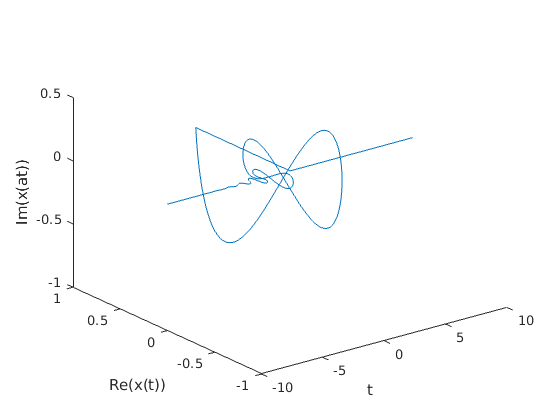

a = 2;

plot3(t, real(x(t)), imag(x(a*t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(at))');

**b) Graficar y(t) en el intervalo **$-10\le t\le 10$

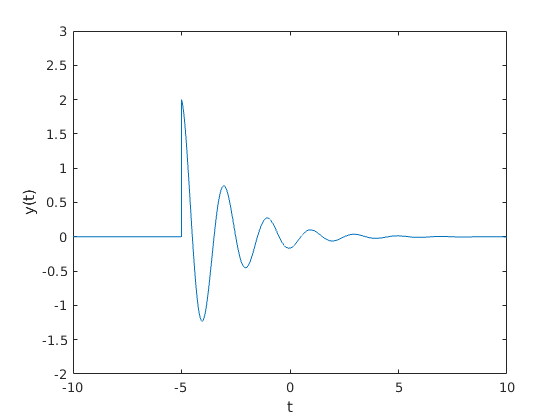

plot(t, y(t));

xlabel('t');
ylabel('y(t)');
axis([-10 10 -2 3]);

**c) Integracón numérica para calcular la energía de x(t)**

xeFun = @(t) abs(x(t)).^2;
E_x = integral(xeFun,-Inf, Inf)

E_x = 0.5000

**d) Integración numérica para calcular la energía de  y(t)**

yeFun = @(t) abs(y(t)).^2;
E_y = integral(yeFun, -Inf, inf)

E_y = NaN

**Inciso extra: e) Graficar x(t) sobre el intervalo de **$-10\le t\le 10$

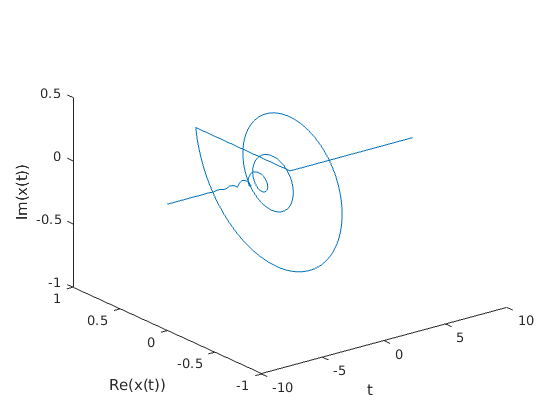

t = [ -10: 0.001: 10];
plot3(t, real(x(t)), imag(x(t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(t))');

## Problema 6 Construcción de la App

**Se adjunta la imagen  de la interfaz de la aplicación y también el enlace para descargar el **[ archivo .mlapp](https://github.com/DemondAngel/SySPractica2/blob/main/PRACTICA2.mlapp)** .**

**Enlace del **[código](https://drive.google.com/file/d/1K5_zRndBV_JYnFMJnr31azNiMN-x1XGE/view?usp=sharing)** en Google Drive**